clear all
clc
n = 12;
Sb = 100e6;
datos_linea = [4 5 0.01 1j*0.068 1j*0.0348; 4 6 0.017 1j*0.092 1j*0.0549; 5 7 0.011308 1j*0.02832 1j*0.0317638; 6 9 0.039 1j*0.1738 1j*0.0358; 6 12 0.023 1j*0.18 1j*0.0236; 7 8 0.008477 1j*0.057522 1j*0.158821; 8 9 0.0119 1j*0.1008 1j*0.0209; 10 11 0.031 1j*0.123 1j*0.0123];
X_tridevanado = [0.06 0.07 0.025; 350e6 200e6 150e6];
Y = Impedancias_tridevanado(X_tridevanado, Sb);
datos_trafos = [1 4 10 Y(1) Y(2) Y(3) 0.1 0.02 0 0 330; 2 7 0 0.05 0 0 0 0 30 0 0; 3 9 0 0.08 0 0 0 0 -30 0 0; 11 12 0 0.1 0 0 0.1 0.02 -30 0 0];
disp('Info del sistema')

Info del sistema


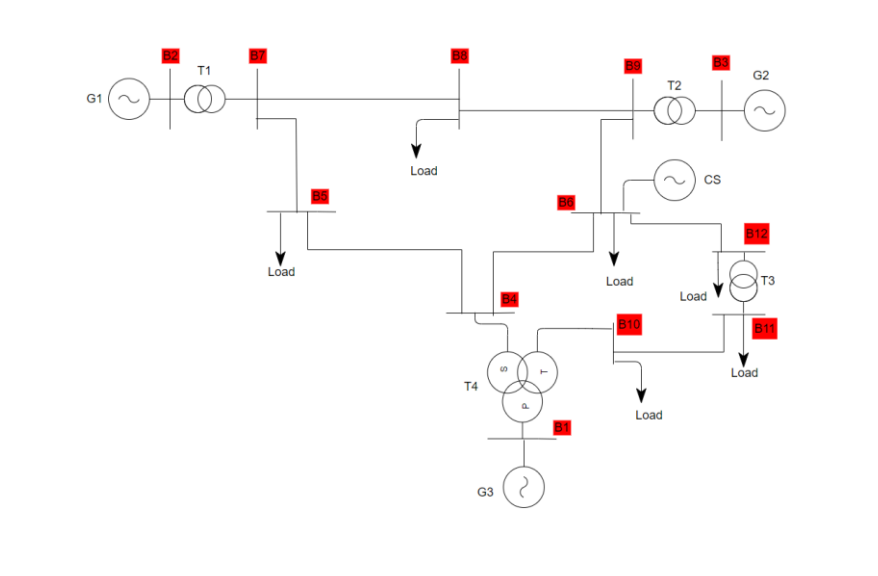

SP = imread('Sistema_potencia_ejp.png');
imshow(SP)

disp('Líneas : ')

Líneas : 


for i = 1:length(datos_linea(:,1))
    l = ['Linea ', num2str(i), ': ', num2str(datos_linea(i,1)), ' - ', num2str(datos_linea(i,2))];
    disp(l)
end

Linea 1: 4 - 5


Linea 2: 4 - 6


Linea 3: 5 - 7


Linea 4: 6 - 9


Linea 5: 6 - 12


Linea 6: 7 - 8


Linea 7: 8 - 9


Linea 8: 10 - 11


disp('Trafos: ')

Trafos: 


for i = 1:length(datos_trafos(:,1))
    if datos_trafos(i,3) ~= 0 && datos_trafos(i,7) ~= 0
        l = ['Trafo tridevanado : ', num2str(datos_trafos(i,1)), ' - ', num2str(datos_trafos(i,2)), ' - ', num2str(datos_trafos(i,3)), ' -- ', 'LTC : ', num2str(datos_trafos(i,7)), '/', num2str(datos_trafos(i,8))];
    elseif datos_trafos(i,3) ~= 0
        l = ['Trafo tridevanado : ', num2str(datos_trafos(i,1)), ' - ', num2str(datos_trafos(i,2)), ' - ', num2str(datos_trafos(i,3))];
    elseif datos_trafos(i,3) == 0 && datos_trafos(i,7) ~= 0
        l = ['Trafo ', num2str(i), ' : ', num2str(datos_trafos(i,1)), ' - ', num2str(datos_trafos(i,2)), ' -- ', 'LTC : ', num2str(datos_trafos(i,7)), '/', num2str(datos_trafos(i,8))];
    else
        l = ['Trafo ', num2str(i), ' : ', num2str(datos_trafos(i,1)), ' - ', num2str(datos_trafos(i,2))];
    end
    disp(l)
end

Trafo tridevanado : 1 - 4 - 10 -- LTC : 0.1/0.02


Trafo 2 : 2 - 7


Trafo 3 : 3 - 9


Trafo 4 : 11 - 12 -- LTC : 0.1/0.02


LTC = datos_trafos(datos_trafos(:,7) ~= 0, :);
Q1 = input('¿Desea desconectar una línea? \n Sí: 1 - No: 2 \n');
if Q1 == 1
    line = input('¿Qué línea desea desconectar?');
else
    line = false;
end
pasos = [];
for i = 1:length(LTC)
    if LTC(i,3) ~= 0
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(i,1)), ' - ', num2str(LTC(i,2)), ' - ', num2str(LTC(i,3)), '? \n'];
    else
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(i,1)), ' - ', num2str(LTC(i,2)), '? \n'];
    end
    Q2 = input(ltc);
    pasos(i) = Q2;
end

Index exceeds matrix dimensions.

Y_barra = Matriz_Ybarra(datos_linea,n,line,datos_trafos,pasos)